# **Metoda celor mai mici patrate**

**Este o metoda prin care:**

- Vrem sa aproximam o functie necunoscuta (printr-un polinom sau  o combinatie de functii de baza)

- Sau sa estimam parametrii intr-un model (traiectorie, populatie)

- Obiectivul: sa minimizam eroarea totala intre valorile relae si cele generate de model

**Scop**

####     Gaseste cea mai buna aproximare $\phi^* \left(x\right)=\arg \;\min \;||f-\phi ||^2 ,\phi \in \Phi$

unde

- Φ este un spatiu de functii

- Norma $||\cdot ||$este definita in functie de un produs scalar (discret sau continuu)

# **Formula generala pentru MPP discret**

    Presupunem ca avem $\left(x_k ,y_k \right),k=1,\ldotp \ldotp \ldotp \ldotp ,m$ si vrem sa aproximam cu o functie de forma:

####                 $\phi \left(x\right)=a_0 \left(\phi_j \phi_k \;\right)=\left(f,\phi_k \right)$,pentru k = 0,...,n

x = [-1, 2, -3];      % Puncte discrete
y = [1, 3, 9];        % f(x) = x^2

n = 2;  % Gradul maxim al polinomului

% Construim baza {1, x, x^2}
baza = cell(1, n+1);
for k = 0:n
    baza{k+1} = @(x) x.^k;
end

[a, phi] = mmp_discret(x, y, baza);
fprintf("Coeficientii aproximantului:\n"); disp(a);

Coeficientii aproximantului:
   -0.2000
   -0.2667
    0.9333



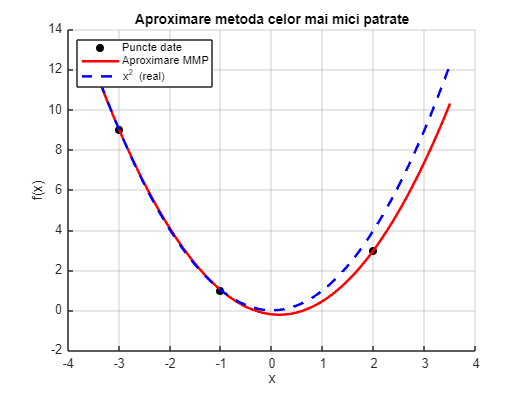

% Grafic
xx = linspace(-3.5, 3.5, 200);
yy_aprox = polyval(flip(a'), xx);
yy_real = xx.^2;

figure; clf;              % deschide fereastra noua și o curăță
hold on;                  % menține curbele pe același grafic
% Date punctuale
plot(x, y, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Puncte date');
% Aproximarea MMP
plot(xx, yy_aprox, 'r-', 'LineWidth', 2, 'DisplayName', 'Aproximare MMP');
% Functia reala (x^2)
plot(xx, yy_real, 'b--', 'LineWidth', 2, 'DisplayName', 'x^2 (real)');
% Etichete
legend('Location', 'northwest');
xlabel('x'); ylabel('f(x)');
title('Aproximare metoda celor mai mici patrate');
grid on;
hold off;

# **Formula generala pentru MPP continuu**

    MPP continuu este o varianta a metodei in care:

- functia data f(x) este cunoscuta pe un interval continuu $\left\lbrack a,b\right\rbrack$

- nu avem doar puncte, ci vrem sa aproximam functia printr-un ansamblu de functii de baza, folosind integrale ca produs scalar:

####                                                     
$$\langle f,g\rangle =\int_a^b f\left(x\right)\cdot g\left(x\right)\mathrm{dx}\;\;$$


f = @(x) x.^3 - 2*x.^2 + x;  % functia reala

% Baza polinomiala: {1, x, x^2, x^3}
baza = {@(x) ones(size(x)), @(x) x, @(x) x.^2, @(x) x.^3};

% Intervalul de lucru
a_int = 0;
b_int = 2;

% Aplicam MPP continuu
[a, phi] = mmp_continuu(f, baza, a_int, b_int);
fprintf("Coeficienti MPP continuu:\n"); disp(a);

Coeficienti MPP continuu:
   -0.0000
    1.0000
   -2.0000
    1.0000

